# Analyzing MSWind23 Raw Data

Pointing to a sample h5file

h5FileStr='G:\Team Drives\Semeter-Research in Progress\pfisr20140425\20140425.001\d0394107.dt0.h5';

Display contents of the h5 file

h5disp(h5FileStr,'/','min');

HDF5 d0394107.dt0.h5 
Group '/' 
    Group '/CohCode' 
        Group '/CohCode/Data' 
            Dataset 'Beamcodes' 
            Dataset 'PulsesIntegrated' 
            Dataset 'Pulsewidth' 
            Dataset 'TxBaud' 
            Group '/CohCode/Data/Power' 
                Dataset 'Data' 
                Dataset 'Range' 
        Group '/CohCode/Mode' 
            Dataset 'Dll' 
            Dataset 'Name' 
            Dataset 'Type' 
            Dataset 'Version' 
            Dataset 'VersionDate' 
    Group '/Integration' 
        Dataset 'MissedPulses' 
    Group '/Raw11' 
        Group '/Raw11/Mode' 
            Dataset 'Dll' 
            Dataset 'Name' 
            Dataset 'Type' 
            Dataset 'Version' 
            Dataset 'VersionDate' 
        Group '/Raw11/Raw' 
            Dataset 'Beamcodes' 
            Dataset 'PulsesIntegrated' 
            Dataset 'Pulsewidth' 
            Dataset 'TxBaud' 
            Group '/Raw11/Raw/Power' 
                Dataset 'Data' 


Number of pulses within a record

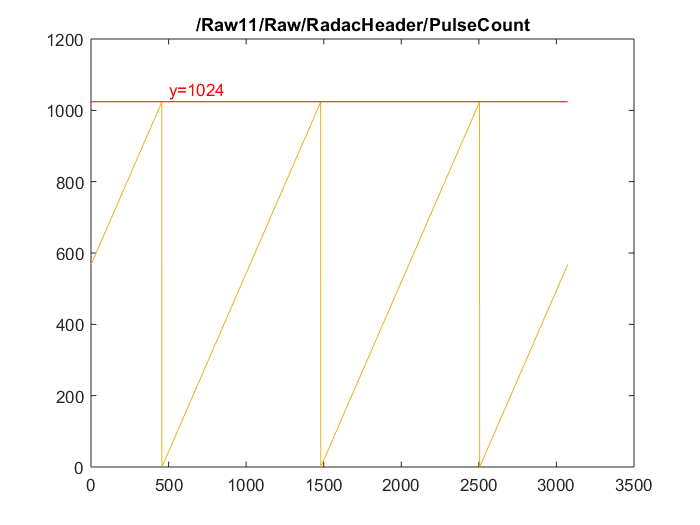

h5DataLoc = '/Raw11/Raw/RadacHeader/PulseCount';
raw.pulseCount=plot_h5_dataset(h5FileStr,h5DataLoc);
line([0 size(raw.pulseCount,1)],[1024 1024],'color','r'); text(500,1060,'y=1024','Color','r');

The beam code of pulses within a record

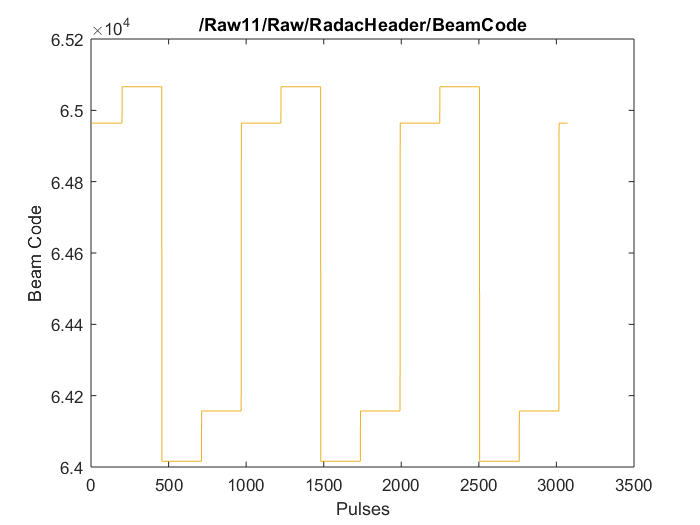

h5DataLoc = '/Raw11/Raw/RadacHeader/BeamCode';
raw.beamCode=plot_h5_dataset(h5FileStr,h5DataLoc);
ylabel('Beam Code');
xlabel('Pulses');

Number of samples of the rececived signals

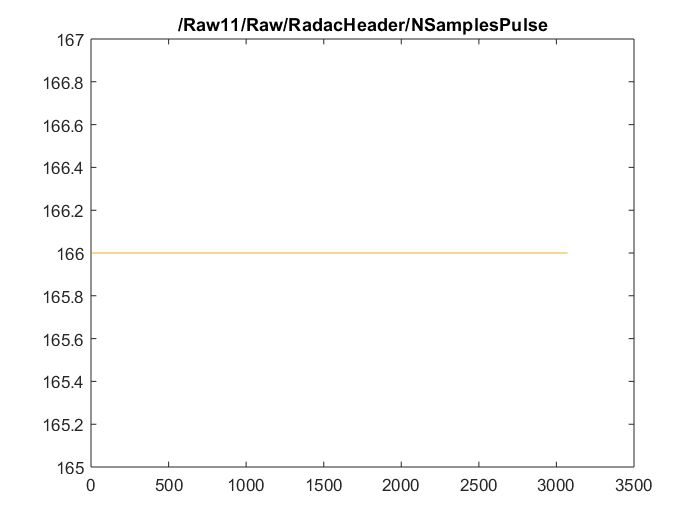

h5DataLoc = '/Raw11/Raw/RadacHeader/NSamplesPulse';
plot_h5_dataset(h5FileStr,h5DataLoc);

Frame Count: corresponds to number of times the TUF files is cycled through

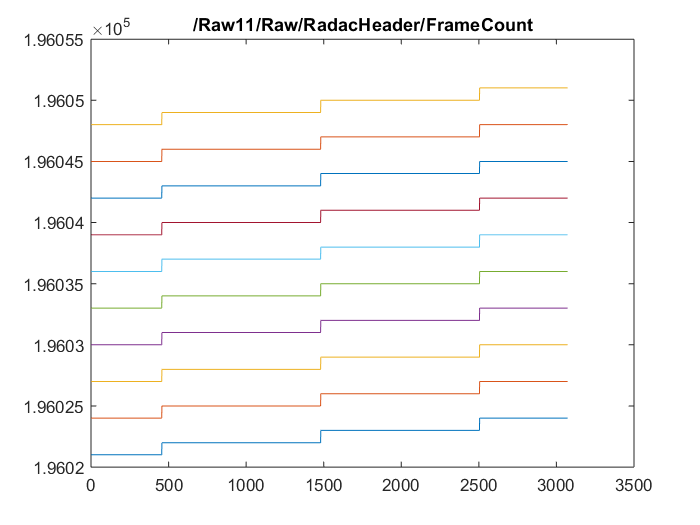

h5DataLoc = '/Raw11/Raw/RadacHeader/FrameCount';
plot_h5_dataset(h5FileStr,h5DataLoc);

RadacTime: Unix time of the header sync call before transmitting each pulse (header sync call in the TUF file)

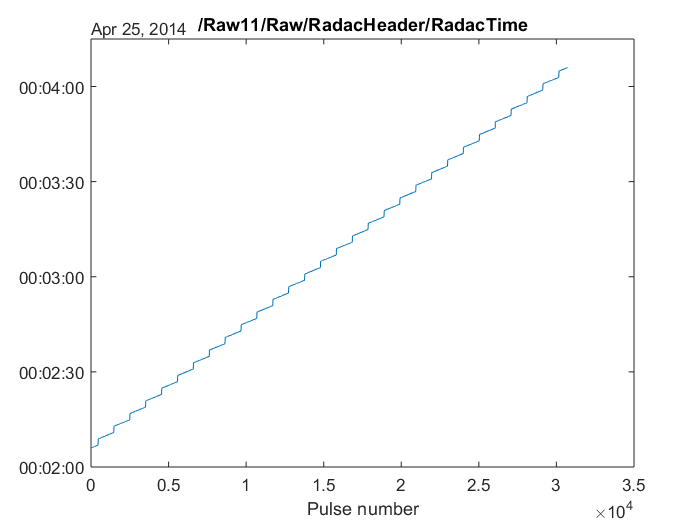

h5DataLoc = '/Raw11/Raw/RadacHeader/RadacTime';
radacTime=h5read(h5FileStr,h5DataLoc);
plot(datetime(datevec(unix_to_matlab_time(radacTime))));
title(h5DataLoc);
xlabel('Pulse number');

**Cycling between beams in RADAC Time**

Note the gap between the 4 beam cycles is filled with other PFISR modes. For example, in this case the radac is transmitting and listening to Alternating Code and Long pulses. 

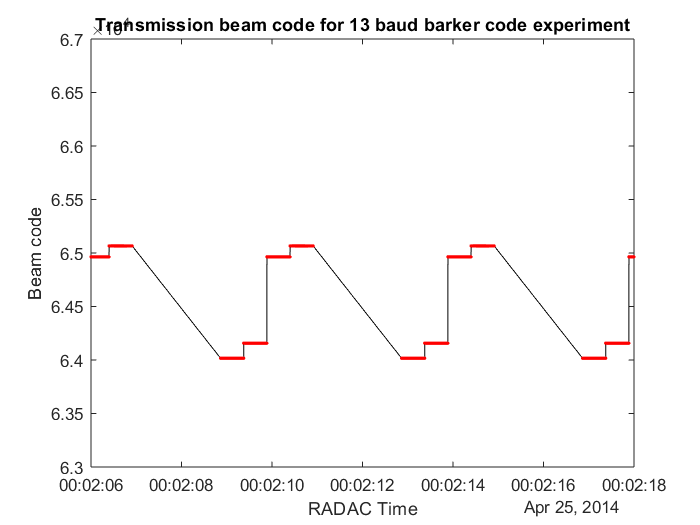

figure;
plot(datetime(datevec(unix_to_matlab_time(radacTime(:,1)))),raw.beamCode(:,1),'.-k','MarkerEdgeColor','r');
xlabel('RADAC Time');
ylabel('Beam code');
ylim([63000 67000]);
title('Transmission beam code for 13 baud barker code experiment');

# Barker code

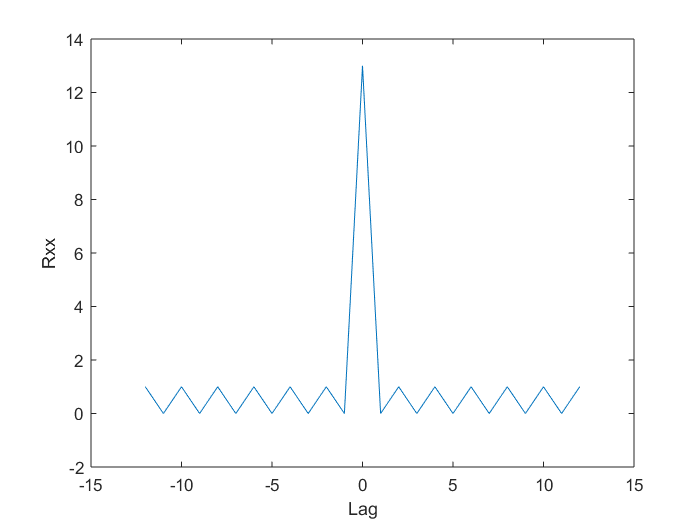

barkerCode13=[+1 +1 +1 +1 +1 -1 -1 +1 +1 -1 +1 -1 +1];
K0 = length(barkerCode13);
figure;
plot(-(K0-1):K0-1,xcorr(barkerCode13));
xlabel('Lag'); ylabel('Rxx');

Over-sampled barker code by a factor of two

barkerCode13OverSampled=[+1 +1 +1 +1 +1 +1 +1 +1 +1 +1 -1 -1 -1 -1 +1 +1 +1 +1 -1 -1 +1 +1 -1 -1 +1 +1];
K = length(barkerCode13OverSampled);


**Demonstrating matchfiltering using XCORR function **

Results in an output which has N+K-1 length of the Barker code; N length of recieved signal, K length of the transmitted signal frame

p=panel();
p.pack(2,2);
p(1,1).select();
[y,x]=xcorr(barkerCode13OverSampled);
nxcorr=2*K-1;
plot(x,y);
ylabel('xcorr of BarkerCode');
xlabel('Lags');
xlim([-(K-1) K-1]);
ylim([0 26]);
text(K-20,4,['#points = ',num2str(nxcorr)]);


**Match filtering using CONV function** with (N+K-1) length of output

p(1,2).select();
y=conv(barkerCode13OverSampled,fliplr(conj(barkerCode13OverSampled)));
nx=2*K-1;
x = -(K-1):K-1;
plot(x,y);
ylabel([{'conv of BC with','time-reversed BC'}]);
xlabel('Lags');
xlim([-(K-1) K-1]);
ylim([0 26]);
text(K-20,4,['#points = ',num2str(nx)]);

**Match filtering using CONV function and shape:'center' option** with (N) length of output

p(2,1).select();
y=conv(barkerCode13OverSampled,fliplr(conj(barkerCode13OverSampled)),'same');
nx=K;
plot(-K/2+1:K/2,y);
ylabel([{'match-filtering','central conv points'}]);
xlabel('Lags');
xlim([-(K-1) K-1]);
ylim([0 26]);
text(K-20,4,['#points = ',num2str(nx)]);

**Match filtering using CONV function and shape:'valid' option** with (N-K+1) length of output

Valid option returns only the part of the convolution computed without zero-padded edges

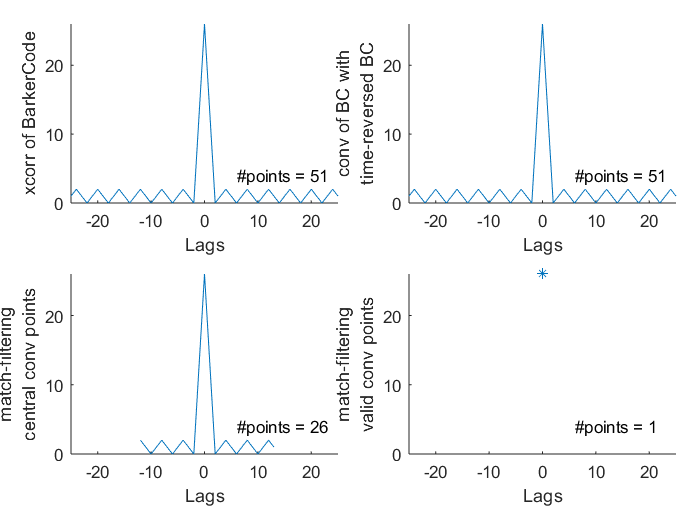

p(2,2).select();
y=conv(barkerCode13OverSampled,fliplr(conj(barkerCode13OverSampled)),'valid');
nx=K-K+1;
plot(nx-1,y,'*');
ylabel([{'match-filtering','valid conv points'}]);
xlabel('Lags');
xlim([-(K-1) K-1]);
ylim([0 26]);
text(K-20,4,['#points = ',num2str(nx)]);

# Step1: Decoding

Initializing

barkerCode=[+1 +1 +1 +1 +1 +1 +1 +1 +1 +1 -1 -1 -1 -1 +1 +1 +1 +1 -1 -1 +1 +1 -1 -1 +1 +1]; %Oversampled by a factor of 2
h5FileStr='G:\Team Drives\Semeter-Research in Progress\pfisr20140425\20140425.001\d0394107.dt0.h5';
h5DataLoc = '/Raw11/Raw/Samples/Data';
rawData = h5read(h5FileStr,h5DataLoc);
h5DataLoc = '/Raw11/Raw/Samples/Range';
range = h5read(h5FileStr,h5DataLoc);
nRanges = length(range);
nRecords = size(rawData,4);
nPulsesPerRecord = size(rawData,3);
nRanges = size(rawData,2);

Converting the Raw Data matrix into a cell array in order matchfilter without for loops

% realSignal = mat2cell(reshape(squeeze(rawData(1,:,:,:)),nRanges,nPulsesPerRecord*nRecords),nRanges,ones(1,nPulsesPerRecord*nRecords));
% imagSignal = mat2cell(reshape(squeeze(rawData(2,:,:,:)),nRanges,nPulsesPerRecord*nRecords),nRanges,ones(1,nPulsesPerRecord*nRecords));
signal = mat2cell(reshape(squeeze(rawData(1,:,:,:)+1i*rawData(2,:,:,:)),nRanges,nPulsesPerRecord*nRecords),nRanges,ones(1,nPulsesPerRecord*nRecords));

**Barker-code Decoding:** Matchfiltering with the oversampled barker code, and converting the cell arrays back to matrices 

decodedSignal = cell2mat(cellfun(@(x) conv(x,fliplr(conj(barkerCode)),'valid'),signal,'UniformOutput',false )); 
% decodedSignalReal = cell2mat(cellfun(@(x) conv(x,fliplr(conj(barkerCode)),'valid'),realSignal,'UniformOutput',false )); 
% decodedSignalImag = cell2mat(cellfun(@(x) conv(x,fliplr(conj(barkerCode)),'valid'),imagSignal,'UniformOutput',false )); 

# Step 2a: Raw power

h5DataLoc = '/Raw11/Raw/RadacHeader/BeamCode';
raw.beamCode=h5read(h5FileStr,h5DataLoc);
h5DataLoc = '/Raw11/Raw/RadacHeader/RadacTime';
raw.radacTime=h5read(h5FileStr,h5DataLoc);

Calculating signal power

signalPower = abs((decodedSignal)).^2;

Separating out the signal in different beams

uniqueBeamCodes = num2cell(unique(raw.beamCode(:)));
beamIndx = cell2mat((cellfun(@(x) beam_filter(raw.beamCode(:),x),uniqueBeamCodes,'UniformOutput',false ))'); 
nSamplesAfterDecoding=size(signalPower,1)-1; %removing the last sample to match with SRI output
nPulsesInBeam=size(beamIndx,1);
nBeams=size(beamIndx,2);
signalBeam=reshape(signalPower(1:nSamplesAfterDecoding,beamIndx),nSamplesAfterDecoding,nPulsesInBeam,nBeams);
rangeAfterDecoding=range(1:nSamplesAfterDecoding);

**Integrating Power**

nPulsesIntegrated = 768; % 768*2ms!
nRecords=nPulsesInBeam./nPulsesIntegrated;
integratedPower = squeeze(sum(reshape(permute(signalBeam,[2 3 1]),nPulsesIntegrated,nRecords,nBeams,nSamplesAfterDecoding)));

**Stitching different powers together**

Need to write this, less priority.

# Step2b: Calculating Power Spectra

h5DataLoc = '/Raw11/Raw/RadacHeader/BeamCode';
raw.beamCode=h5read(h5FileStr,h5DataLoc);
h5DataLoc = '/Raw11/Raw/RadacHeader/RadacTime';
raw.radacTime=h5read(h5FileStr,h5DataLoc);

Separating out the signal in different beams

uniqueBeamCodes = num2cell(unique(raw.beamCode(:)));
beamIndx = cell2mat((cellfun(@(x) beam_filter(raw.beamCode(:),x),uniqueBeamCodes,'UniformOutput',false ))'); 
nSamplesAfterDecoding=size(decodedSignal,1)-1; %removing the last sample to match with SRI output
nPulsesInBeam=size(beamIndx,1);
nBeams=size(beamIndx,2);
signalBeam=reshape(decodedSignal(1:nSamplesAfterDecoding,beamIndx),nSamplesAfterDecoding,nPulsesInBeam,nBeams);
rangeAfterDecoding=range(1:nSamplesAfterDecoding);

Generating Power Spectra: to be continued...

nPulsesForSpectra = 512; % 768*2ms!
nRecords=nPulsesInBeam./nPulsesForSpectra;


**Results and error**

h5DataLoc = '/CohCode/Data/Power/Data';
cohCodePower = permute(h5read(h5FileStr,h5DataLoc),[3 2 1]);
difference = (cohCodePower-integratedPower)./cohCodePower;
display(['Sum of the fractional error between cohCode power and this codes power: ',num2str(100*sum(difference(:))),'%']);

Sum of the fractional error between cohCode power and this codes power: -0.013551%


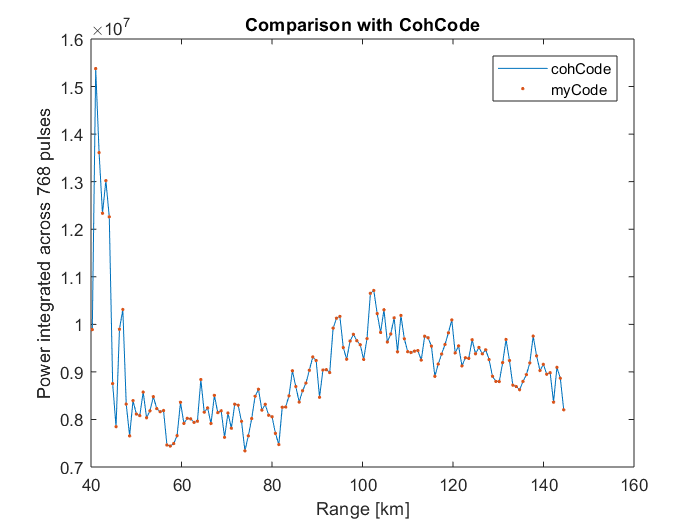

figure;
plot(rangeAfterDecoding/1000,squeeze(cohCodePower(1,1,:))); hold on; plot(rangeAfterDecoding/1000,squeeze(integratedPower(1,1,:)),'.');
xlabel('Range [km]');
ylabel(['Power integrated across ',num2str(nPulsesIntegrated),' pulses']);
legend('cohCode','myCode');
title('Comparison with CohCode')

**Indices for different beams with time**

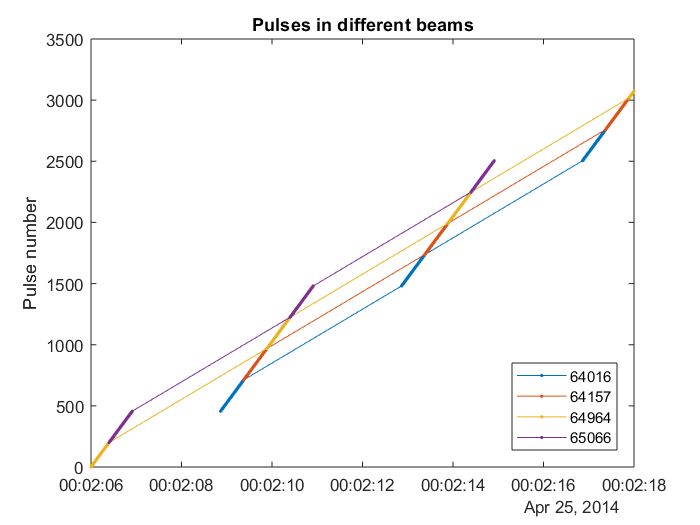

radacTimeArray=raw.radacTime;
figure; 
for i=1:nBeams 
    plot(datetime(datevec(unix_to_matlab_time(radacTimeArray(beamIndx(1:nPulsesIntegrated,i))))),beamIndx(1:nPulsesIntegrated,i),'.-'); 
    hold on; 
end
legend(string(uniqueBeamCodes),'location','southeast');
ylabel('Pulse number');
title('Pulses in different beams');

# Functions

**plot_h5_dataset.m **Function to plot and store 1-D dataset

function plotVariable=plot_h5_dataset(h5FileStr,h5DataLoc)
    plotVariable=h5read(h5FileStr,h5DataLoc);
    plot(plotVariable);
    title(h5DataLoc);
end

**beam_filter.m **Function to find the index of raw signals of a particular beam code

function beamIndx=beam_filter(beamCodeArray,beamCode)
    beamIndx = find(beamCodeArray==beamCode);
end